# MSD Assignment Part 2: Closed - Loop System Identification

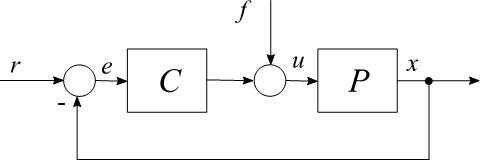

Given Signals: ***f, u, x, e*** (Signal names according to presented architecture, this can vary!)

***x*** includes sensor noise!

## Load Signal Data

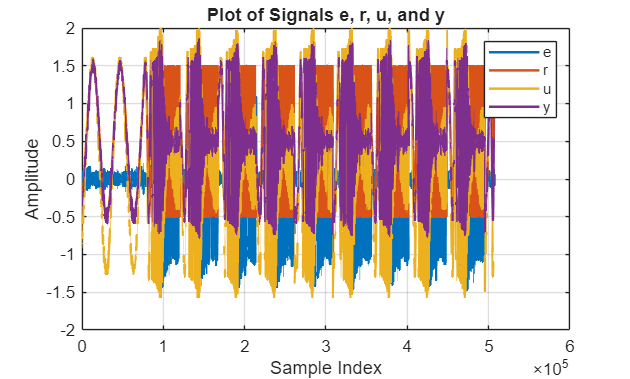

clear all; close all; clc; 

load('MSD2024_P2_Signals.mat', 'e', 'r', 'u', 'y')
shapeit_final = load("A.1_C_final.mat", "shapeit_data"); % Load Final Controller from ShapeIt


% Create a figure
figure;

% Plot each variable
plot(e, 'LineWidth', 1.5); % Plot 'e'
hold on; % Retain the current plot
plot(r, 'LineWidth', 1.5); % Plot 'r'
plot(u, 'LineWidth', 1.5); % Plot 'u'
plot(y, 'LineWidth', 1.5); % Plot 'y'

% Add grid, labels, and legend
grid on;
title('Plot of Signals e, r, u, and y'); % Add title
xlabel('Sample Index'); % Label x-axis
ylabel('Amplitude'); % Label y-axis
legend('e', 'r', 'u', 'y'); % Add legend

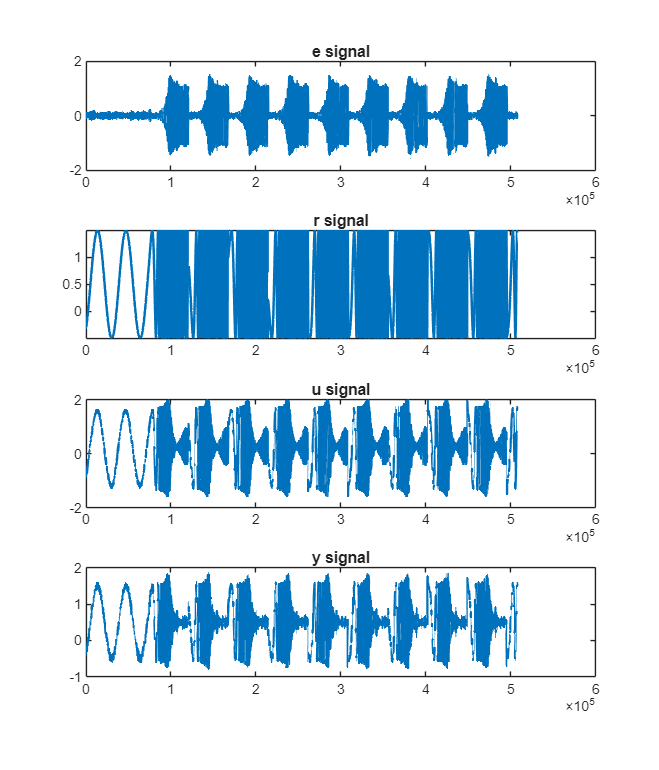


% Increase figure size
figure;
set(gcf, 'Position', [100, 100, 1200, 1400]); % [x y width height]

subplot(4, 1, 1);
plot(e, 'LineWidth', 1.5); % error
title('e signal');
subplot(4, 1, 2);
plot(r, 'LineWidth', 1.5); % reference
title('r signal');
subplot(4, 1, 3);
plot(u, 'LineWidth', 1.5);
title('u signal'); % input, Actuation voltage
subplot(4, 1, 4);
plot(y, 'LineWidth', 1.5);
title('y signal'); % measured position, Displacement of the stage

## Transfer Function Estimate

% Sampling time
Ts = 30e-6;  % 30 microseconds
Fs = 1/Ts;
Nyquist = Fs/2;
t = (0:length(r)-1) * Ts;  % Time vector 

% Get input-output signal pairs
inpt1 = r; % Input signal 1
outpt1 = u; % Output signal 1 (u/r)

inpt2 = r; % Input signal 2
outpt2 = y; % Output signal 2 (y/r)

inpt3 = r; % Input signal 3
outpt3 = e; % Output signal 3 (e/r)

% FFT length for finer frequency resolution
nfft = 2^16;  % Increase FFT length (adjust as needed)

% Use tfestimate() and mscohere() for each input-output pair
wind = hann(10000); % Hann window
[T1, f1] = tfestimate(inpt1, outpt1, wind, [], nfft, Fs); % u/r
[C1, f1] = mscohere(inpt1, outpt1, wind, [], nfft, Fs);

[T2, f2] = tfestimate(inpt2, outpt2, wind, [], nfft, Fs); % y/r
[C2, f2] = mscohere(inpt2, outpt2, wind, [], nfft, Fs);

[T3, f3] = tfestimate(inpt3, outpt3, wind, [], nfft, Fs); % e/r
[C3, f3] = mscohere(inpt3, outpt3, wind, [], nfft, Fs);

[T4, f4] = tfestimate(outpt1, outpt2, wind, [], nfft, Fs);
[C4, f4] = mscohere(outpt1, outpt2, wind, [], nfft, Fs); % y/u

inpt4_1 = outpt2 * -1;
outpt4_1 = u;

[T4_1, f4_1] = tfestimate(outpt4_1, inpt4_1, wind, [], nfft, Fs);
[C4_1, f4_1] = mscohere(outpt4_1, inpt4_1, wind, [], nfft, Fs); % y/u

[T5, f5] = tfestimate(outpt3, outpt1, wind, [], nfft, Fs);
[C5, f5] = mscohere(outpt3, outpt1, wind, [], nfft, Fs); % u/e

% Recreate estimated controller
C = tf(shapeit_final.shapeit_data.C_tf.Numerator, shapeit_final.shapeit_data.C_tf.Denominator)


C =
 
  0.01098 s^4 + 16.38 s^3 + 2.412e05 s^2 + 3.075e08 s + 8.062e10
  --------------------------------------------------------------
       0.001989 s^4 + 56.2 s^3 + 7.029e04 s^2 + 2.139e07 s
 
Continuous-time transfer function.
Model Properties


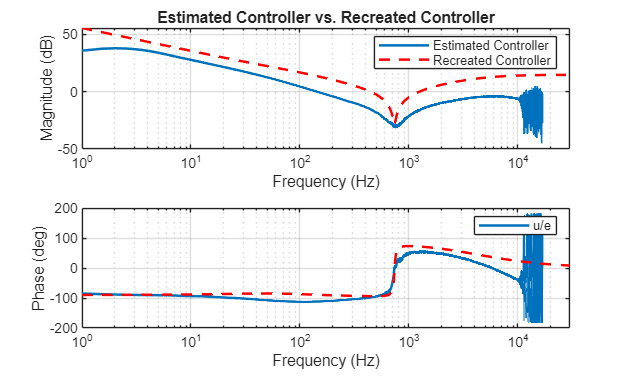


% Generate frequency response for C(s)
[mag_C, phase_C, freq_C] = bode(C, {2*pi*1, 2*pi*30000}); % Convert Hz to rad/s
mag_C = squeeze(mag_C); % Remove singleton dimensions
phase_C = squeeze(phase_C); % Remove singleton dimensions
freq_C = freq_C / (2*pi); % Convert rad/s back to Hz

% Plot Closed-Loop Identified Sensitivities
figure(1); clf(1);

% Magnitude plots
subplot(2, 1, 1);
% semilogx(f1, mag2db(abs(T1)), 'LineWidth', 1.5); hold on;
% semilogx(f2, mag2db(abs(T2)), 'LineWidth', 1.5); hold on;
% semilogx(f3, mag2db(abs(T3)), 'LineWidth', 1.5); hold on;
% semilogx(f4, mag2db(abs(T4)), 'LineWidth', 1.5); hold on;
% semilogx(f4_1, mag2db(abs(T4_1)), 'LineWidth', 1.5); hold on;
semilogx(f5, mag2db(abs(T5)), 'LineWidth', 1.5); hold on;
semilogx(freq_C, mag2db(mag_C), 'r--', 'LineWidth', 1.5); % Add controller response
xlabel('Frequency (Hz)'); xlim([1, 30000]); % Set x-axis limits
ylabel('Magnitude (dB)');
legend('Estimated Controller', 'Recreated Controller')
grid on;
title('Estimated Controller vs. Recreated Controller');

% Phase plots
subplot(2, 1, 2);
% semilogx(f1, rad2deg(angle(T1)), 'LineWidth', 1.5); hold on;
% semilogx(f2, rad2deg(angle(T2)), 'LineWidth', 1.5); hold on;
% semilogx(f3, rad2deg(angle(T3)), 'LineWidth', 1.5); hold on;
% semilogx(f4, rad2deg(angle(T4)), 'LineWidth', 1.5); hold on;
% semilogx(f4_1, rad2deg(angle(T4_1)), 'LineWidth', 1.5); hold on;
semilogx(f5, rad2deg(angle(T5)), 'LineWidth', 1.5); hold on;
semilogx(freq_C, phase_C, 'r--', 'LineWidth', 1.5); % Add controller response
xlabel('Frequency (Hz)'); xlim([1, 30000]); % Set x-axis limits
ylabel('Phase (deg)');
legend('u/e');
grid on;


% % Coherence plots
% subplot(3, 1, 3);
% % semilogx(f1, C1, 'LineWidth', 1.5); hold on;
% % semilogx(f2, C2, 'LineWidth', 1.5); hold on;
% % semilogx(f3, C3, 'LineWidth', 1.5); hold on;
% % semilogx(f4, C4, 'LineWidth', 1.5); hold on;
% % semilogx(f4_1, C4_1, 'LineWidth', 1.5); hold on;
% semilogx(f5, C5, 'LineWidth', 1.5); hold on;
% xlabel('Frequency (Hz)'); xlim([1, 30000]); % Set x-axis limits
% ylabel('Coherence');
% grid on;


## Obtain Plant Model from Closed-Loop Senstivities

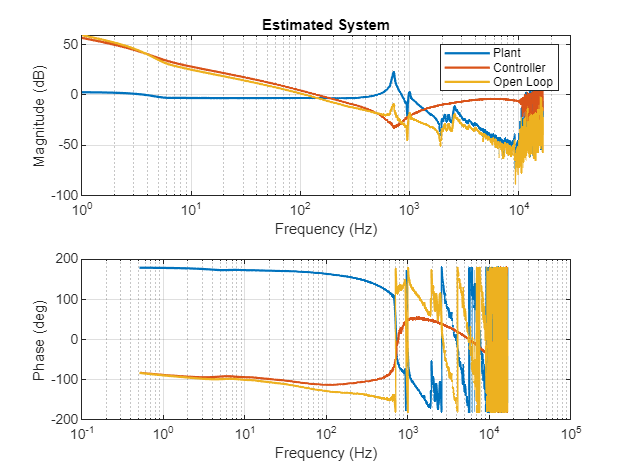

% Pestimate4 = -T3./T1; % -(e/r)/(u/r)
% 
% Pestimate3 = -T2./T3; % -(e/r)/(y/r)
% Pestimate2 = T2./T1; % (y/r)/(u/r)

Pestimate = -T2./T1; % -(y/r)/(u/r)
C_estimate = T1./T3; % (u/r) / (e/r)
PC_estimate = T2./T3; % (y/r) / (e/r)

% Plot Plant
figure(1);clf(1);
subplot(2,1,1);
% semilogx(f1,mag2db(abs(Pestimate4)), 'LineWidth', 1.5); hold on;
% semilogx(f1,mag2db(abs(Pestimate2)), 'LineWidth', 1.5); hold on;
% semilogx(f1,mag2db(abs(Pestimate3)), 'LineWidth', 1.5); hold on;
semilogx(f1,mag2db(abs(Pestimate)), 'LineWidth', 1.5); hold on;
semilogx(f1,mag2db(abs(C_estimate)), 'LineWidth', 1.5); hold on;
semilogx(f1,mag2db(abs(PC_estimate)), 'LineWidth', 1.5); hold on;
legend('Plant','Controller','Open Loop')
xlabel('Frequency (Hz)'); xlim([1, 30000])
ylabel('Magnitude (dB)')
grid on
title('Estimated System')
subplot(2,1,2);
% semilogx(f1,rad2deg(angle(Pestimate4)), 'LineWidth', 1.5); hold on;
% semilogx(f1,rad2deg(angle(Pestimate2)), 'LineWidth', 1.5); hold on;
% semilogx(f1,rad2deg(angle(Pestimate3)), 'LineWidth', 1.5); hold on;
semilogx(f1,rad2deg(angle(Pestimate)), 'LineWidth', 1.5); hold on;
semilogx(f1,rad2deg(angle(C_estimate)), 'LineWidth', 1.5); hold on
semilogx(f1,rad2deg(angle(PC_estimate)), 'LineWidth', 1.5); hold on;

xlabel('Frequency (Hz)')
ylabel('Phase (deg)')
grid on



% % Nyquist Plot
% figure(2); clf(2);
% plot(real(Pestimate4), imag(Pestimate4), 'LineWidth', 1.5); hold on;
% % plot(real(Pestimate4), imag(Pestimate4), 'LineWidth', 1.5); hold on;
% set(gcf, 'Position', [100, 100, 1000, 1000]);
% 
% % Adding labels and legends
% xlabel('Real Part');
% ylabel('Imaginary Part');
% grid on;
% legend('Pestimate2 (T2/T1)', 'Pestimate4 (-T2/T1)');
% title('Nyquist Plot of Estimated Plant Models');
% axis equal; % Make sure the scale is the same for both axes